# Disease surveillance cost data exploration

BACKGROUND ON GOAL

We start by investigating the National Health Accounts data to understand the data format and how to clean the data in a script. We will eventually combine the national health accounts data with the donor data to obtain an estimate of total global spend.

rootPath = "C:/Users/sebqu/OneDrive/Documents/GitHub/pandemic_model"; % Write path helper functions later
rawDir = rootPath + "/data/raw/IHME_HEALTH_SPENDING_2000_2017_ESTIMATES_CSV";
filePaths = dir(rawDir + "/*.csv")

filePaths = 195×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


Load all of the data into one big file so you can clean all country data simultaneously.

numFiles = length(filePaths);
countryData = cell(1, numFiles);
for i = 1:numFiles
    data = readtable(rawDir + "/" + filePaths(i).name);
    yearFilter = data.year == 2017; % Only interested in latest available data.
    countryData{i} = data(yearFilter,:);
end

rawData = vertcat(countryData{:});

Do a bit of simple cleaning to reduce code clutter later.

rawData.variable(rawData.variable == "Health expenditures as a percentage of total health expenditures") = {'share'};
rawData.variable(rawData.variable == "Health expenditures in 2017 USD (millions)") = {'total (millions)'};
rawData.variable(rawData.variable == "Health expenditures per capita in 2017 USD") = {'per capita'};

Check which countries have estimates for HC6.5 (epi surveillance and risk and disease control programs).

There are also data on what share of total health expenditures they constitute. You can analyze this to help get the right numbers.

Let's start by cutting the data down to everything related to epi surveillance.

surveillanceData = rawData(rawData.hc == 6.5,:);
head(surveillanceData)

     iso3      location_id     location_name     year    hc                                         hc_name                                         hp                  hp_name                       variable          value    lower    upper
    _______    ___________    _______________    ____    ___    ________________________________________________________________________________    ___    _________________________________    ____________________    _____    _____    _____

    {'AFG'}        160        {'Afghanistan'}    2017    6.5    {'6.5 Prevention care - Epi surveillance and ri

Print list of healthcare providers that spend on Epi surveillance.

uniqueProviders = unique(surveillanceData.hp_name)

uniqueProviders = 21×1 cell array
    {'1. Hospitals'                                                     }
    {'1.1 Hospitals - General'                                          }
    {'1.2 Hospitals - Mental health'                                    }
    {'1.3 Hospitals - Specialized'                                      }
    {'1.nec Hospitals - Other'                                          }
    {'2. Resid. long-term care fac.'                                    }
    {'3. Providers of ambulatory care'                                  }
    {'3.1 Providers of ambulatory care - Medical practices'             }
    {'3.2 Providers of ambulatory care - Dental practices'              }
    {'3.3 Providers of ambulatory care - Other practices'               }
    {'3.4 Providers of ambulatory care - Ambulatory health care centers'}
    {'3.5 Providers of home health care services'                       }
    {'3.nec Providers of ambulatory care - NEC'                         }
    

**Ask Catherine and Chris which of these healthcare providers we should use in our estimate. **For now, we just use all of them and use the crude method adopted by [Donor Tracker](https://donortracker.org/publications/learning-covid-19-stronger-financing-disease-surveillance).

surveillanceDataAgg = groupsummary(surveillanceData, ["location_name", "variable"], 'sum', ["value", "lower", "upper"]);
surveillanceDataAgg.GroupCount = [];
surveillanceDataAgg = surveillanceDataAgg(surveillanceDataAgg.variable ~= "per capita",:);

It would be useful to plot both the shares and the totals to get a sense of the distribution. Should also include the zeros as a note on the figures.

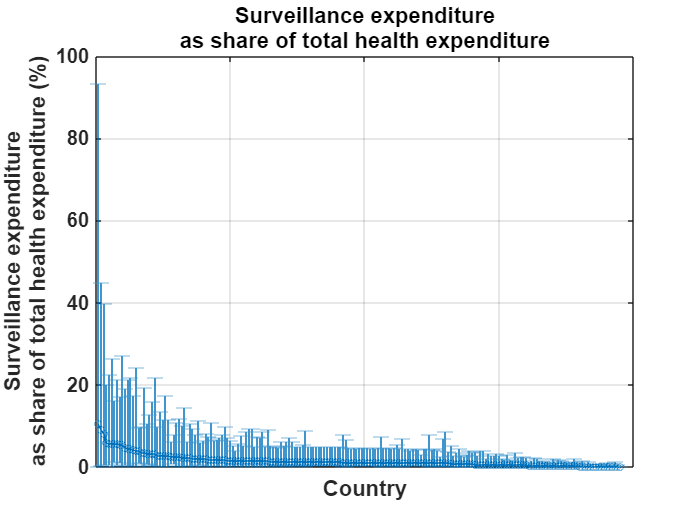

surveillanceSharesAgg = surveillanceDataAgg(surveillanceDataAgg.variable == "share",:);
surveillanceSharesAgg = sortrows(surveillanceSharesAgg, "sum_value", "descend");
errorbar( ...
    1:length(surveillanceSharesAgg.location_name), ...
    surveillanceSharesAgg.sum_value, ...
    surveillanceSharesAgg.sum_value - surveillanceSharesAgg.sum_lower, ...
    surveillanceSharesAgg.sum_upper - surveillanceSharesAgg.sum_value, ...
    'o-', 'LineWidth', 0.3, 'MarkerSize', 4, 'CapSize', 10);
xlabel("Country");
ylabel({"Surveillance expenditure"; "as share of total health expenditure (%)"});
title({"Surveillance expenditure"; "as share of total health expenditure"});
grid on;
set(gca, 'FontSize', 12, 'FontWeight', 'bold');
xticklabels({});

% Style the plot
set(gcf, 'Color', 'w');  % Set background color to white


Print top ten surveillance expending countries as share of total health expenditure.

surveillanceSharesAgg(1:10,["location_name", "sum_value", "sum_lower", "sum_upper"])

ans = 10×4 table
     location_name     sum_value    sum_lower    sum_upper
    _______________    _________    _________    _________

    {'Madagascar' }      10.5            0         93.4   
    {'Mali'       }       9.1          0.4         44.9   
    {'Guyana'     }       8.2          0.5         39.7   
    {'Brazil'     }       5.9          0.6         20.1   
    {'India'      }       5.8          0.6         22.5   
    {'Zambia'     }       5.7          0.2         26.5   
    {'Haiti'      }       5.7          1.4         16.3   
    {'South Sudan'}       5.7          0.7         21.2   
    {'DR Congo'   }       5.5          1.2         17.1   
    {'Togo'       }       5.5          0.3         27.1   


We do the same for the totals.

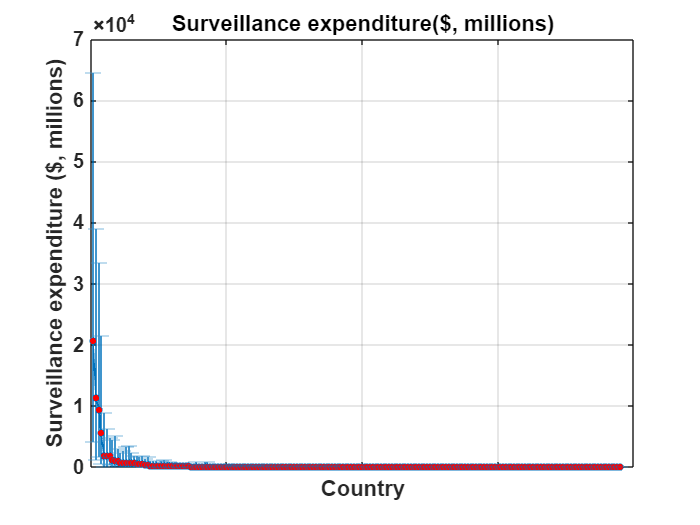

surveillanceTotalsAgg = surveillanceDataAgg(surveillanceDataAgg.variable == "total (millions)",:);
surveillanceTotalsAgg = sortrows(surveillanceTotalsAgg, "sum_value", "descend");
errorbar( ...
    1:length(surveillanceTotalsAgg.location_name), ...
    surveillanceTotalsAgg.sum_value, ...
    surveillanceTotalsAgg.sum_value - surveillanceTotalsAgg.sum_lower, ...
    surveillanceTotalsAgg.sum_upper - surveillanceTotalsAgg.sum_value, ...
    'o-', 'LineWidth', 0.3, 'MarkerSize', 4, 'CapSize', 10, 'MarkerFaceColor', 'red');
xlabel("Country");
ylabel({"Surveillance expenditure ($, millions)"});
title({"Surveillance expenditure($, millions)"});
grid on;
set(gca, 'FontSize', 12, 'FontWeight', 'bold');
xticklabels({});

% Style the plot
set(gcf, 'Color', 'w');  % Set background color to white

surveillanceTotalsAgg(1:10,["location_name", "sum_value", "sum_lower", "sum_upper"])

ans = 10×4 table
     location_name     sum_value    sum_lower    sum_upper
    _______________    _________    _________    _________

    {'USA'        }      20655       4143.4        64535  
    {'Brazil'     }      11408       1173.3        39058  
    {'China'      }     9450.5       1767.8        33470  
    {'India'      }     5680.7       585.32        21560  
    {'Germany'    }     1959.9        62.66         8932  
    {'Japan'      }     1886.6        62.69       6234.9  
    {'Canada'     }     1811.2        365.5       4895.1  
    {'South Korea'}     1298.6        77.65       4425.1  
    {'France'     }     1058.7        47.42       5136.9  
    {'Italy'      }     988.25       185.72       3091.7  


Create first cut of estimates. Multiply central value by 0.375, lower value by 0.25, and upper value by 0.5.

surveillanceTotalGlobe = sum(surveillanceTotalsAgg(:, ["sum_value", "sum_lower", "sum_upper"]));
surveillanceTotalGlobe.sum_value = surveillanceTotalGlobe.sum_value .* 0.375;
surveillanceTotalGlobe.sum_lower = surveillanceTotalGlobe.sum_lower .* 0.25;
surveillanceTotalGlobe.sum_upper = surveillanceTotalGlobe.sum_upper .* 0.5;
surveillanceTotalGlobe = renamevars(surveillanceTotalGlobe, ...
    ["sum_value", "sum_lower", "sum_upper"], ...
    ["central", "2.5pct", "97.5pct"]);
surveillanceTotalGlobe = surveillanceTotalGlobe .* 1e6 % convert to unit dollars

surveillanceTotalGlobe = 1×3 table
     central       2.5pct       97.5pct  
    __________    _________    __________

    2.6862e+10    2.603e+09    1.2492e+11


outPath = fullfile(rootPath, "data/clean/national_surveillance_costs.csv");
writetable(surveillanceTotalGlobe, outPath);

Now check what share of total expenditure is used on surveillance to compare to the 1-3% number used by the [World Bank](https://thedocs.worldbank.org/en/doc/5760109c4db174ff90a8dfa7d025644a-0290032022/original/G20-Gaps-in-PPR-Financing-Mechanisms-WHO-and-WB-pdf.pdf).

surveillanceDataAggWide = unstack(surveillanceDataAgg, ["sum_value", "sum_lower", "sum_upper"], "variable")

surveillanceDataAggWide = 195×7 table
         location_name         sum_value_share    sum_value_total_millions_    sum_lower_share    sum_lower_total_millions_    sum_upper_share    sum_upper_total_millions_
    _______________________    _______________    _________________________    _______________    _________________________    _______________    _________________________

    {'Afghanistan'        }          0.6                    11.27                      0                     0.22                    3.3                    68.23          
    {'Albania'            }          0.6                     6.45                    0.1                     0.75                    2.7                    26.72          
    {'Algeria'            }        

lower_mean_share = 0.25 * sum(surveillanceDataAggWide.sum_lower_share .* surveillanceDataAggWide.sum_lower_total_millions_) ./ sum(surveillanceDataAggWide.sum_lower_total_millions_)

lower_mean_share = 0.0627

central_mean_share = 0.375 * sum(surveillanceDataAggWide.sum_value_share .* surveillanceDataAggWide.sum_value_total_millions_) ./ sum(surveillanceDataAggWide.sum_value_total_millions_)

central_mean_share = 0.7931

upper_mean_share = 0.5* sum(surveillanceDataAggWide.sum_upper_share .* surveillanceDataAggWide.sum_upper_total_millions_) ./ sum(surveillanceDataAggWide.sum_upper_total_millions_)

upper_mean_share = 4.0594

My central estimate for the share of total healthcare expenditure used on disease surveillance is 0.8. This is relatively close to [Kunadu's](https://forum.effectivealtruism.org/posts/pnincG5vW8Far8Ggg/how-well-funded-is-biosecurity-philanthropy#Updates___Corrections) informed upper bound of 1% of government health spending going to all of biosecurity, suggesting our values could be overestimated. However, I don't know if our conception of disease surveillance is a perfect subset of Kunadu's biosecurity concept. I feel unsure how to evaluate this.